# Case3：用风最优分布的案例

clc
clear
close

## 正式开始！

定义一些参数

clc
clear
close

iter_Max=20;
N=200;
range=100;

Vel.us = [2];
Vel.ua = [20];

## 1号组

Model1.Airnode = [234.170	7120.920
                919.440	7212.330
                1444.780	5650.750];
Model1.centrol = [866.130	6661.330];
Model1.Surnode = [234.170	7120.920
                1444.780	5650.750
                2592.250	5030.090];
Model1.CostAir = [800; 800; 800];
Model1.CostSur = [800; 800; 800];
ub = [Model1.Airnode(1,1)+range, Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range, Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 = 1.0e+03 *

    0.3070    7.0324


GBestFitness = 1.0e+03 *

    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045    1.6045


Temp_L1 = 1.0e+03 *

    2.5922    5.0301


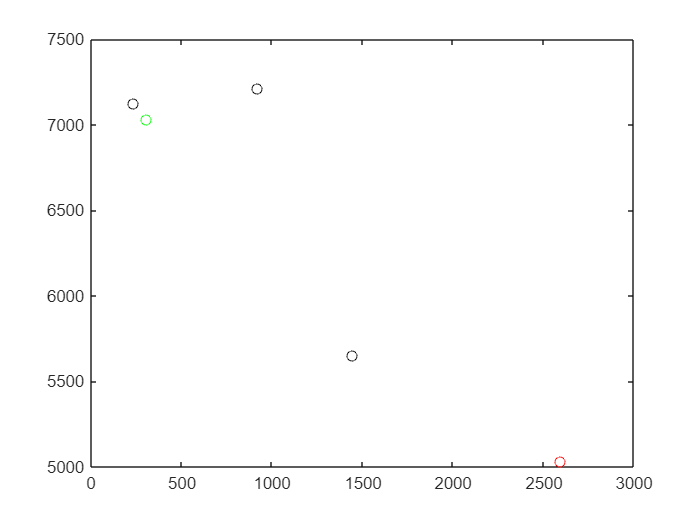


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

Model2.Airnode = [2491.56000000000	5818.42000000000
                  2692.94000000000	4241.75000000000];
Model2.centrol = [2592.25000000000	5030.09000000000];
Model2.Surnode = [1444.78000000000	5650.75000000000
                  2692.94000000000	4241.75000000000
                  1627.39000000000	4043.44000000000];
Model2.CostAir = [800; 800];
Model2.CostSur = [800; 1600; 800];
ub = [Model2.Airnode(1,1)+range,Model2.Airnode(1,2)+range];
lb = [Model2.Airnode(1,1)-range,Model2.Airnode(1,2)-range];

[Temp_T2, GBestFitness, Temp_L2] = PSOsolveTemp(Model2, Vel, ub, lb, iter_Max, N)

Temp_T2 = 1.0e+03 *

    2.3916    5.7184


GBestFitness = 1.0e+03 *

    1.7736    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701    1.7701


Temp_L2 = 1.0e+03 *

    2.6929    4.2417


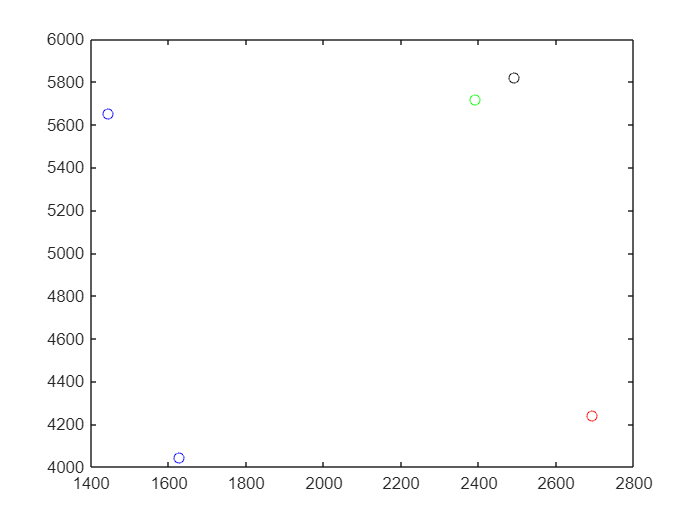


close
figure
plot(Model2.Surnode(:,1),Model2.Surnode(:,2),'bo');
hold on
plot(Model2.Airnode(:,1),Model2.Airnode(:,2),'ko');
plot(Temp_T2(1),Temp_T2(2),'go');
plot(Temp_L2(1),Temp_L2(2),'ro');

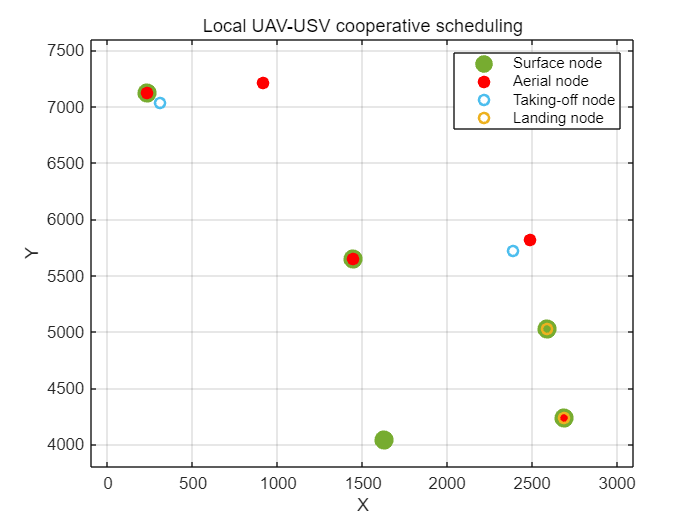

close
Surnode =  [Model1.Surnode
            Model2.Surnode];

Airnode = [Model1.Airnode
            Model2.Airnode];

Temp_T = [Temp_T1
    Temp_T2];

Temp_L = [Temp_L1
    Temp_L2];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([-100 3100 3800 7600])
title('Local UAV-USV cooperative scheduling');
xlabel('X');
ylabel('Y');
grid on;

## 2号组

Model1.Airnode = [4697.22000000000	5888.44000000000
                   7077.42000000000	6344.03000000000];
Model1.centrol = [5887.32000000000	6116.24000000000];
Model1.Surnode = [6774.42000000000	4419.72000000000
                5887.32000000000	6116.24000000000
                6482.36000000000	6230.17000000000];
Model1.CostAir = [800;  800];
Model1.CostSur = [800; 1600; 800];
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 = 1.0e+03 *

    4.7972    5.7884


GBestFitness = 1.0e+03 *

    2.0829    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744    2.0744


Temp_L1 = 1.0e+03 *

    5.8873    6.1162


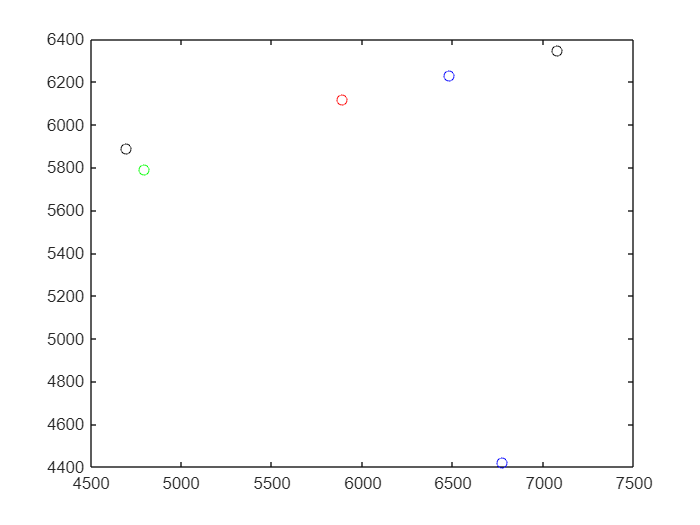


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

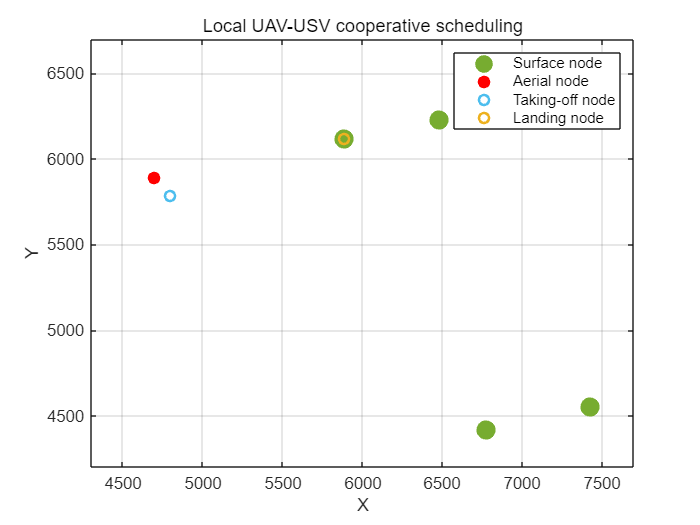

close
Surnode =  [5887.32000000000	6116.24000000000
6482.36000000000	6230.17000000000
7077.42000000000	6344.03000000000
7426.92000000000	4553.86000000000
6774.42000000000	4419.72000000000];

Airnode = [Model1.Airnode];

Temp_T = [Temp_T1];

Temp_L = [Temp_L1];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([4300 7700 4200 6700])
title('Local UAV-USV cooperative scheduling');
xlabel('X');
ylabel('Y');
grid on;

## 3号组

Model1.Airnode = [561.890000000000	3845.08000000000
                  1448.50000000000	2359.83000000000];
Model1.centrol = [1005.20000000000	3102.46000000000];
Model1.Surnode = [2171.36000000000	2512.47000000000
                  725.670000000000	2207.14000000000
                  854.060000000000	926.500000000000];
Model1.CostAir = [800; 800];
Model1.CostSur = [800; 800; 800];
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 = 1.0e+03 *

    0.6619    3.7451


GBestFitness = 1.0e+03 *

    2.6170    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060    2.6060


Temp_L1 = 1.0e+03 *

    1.1623    2.2994


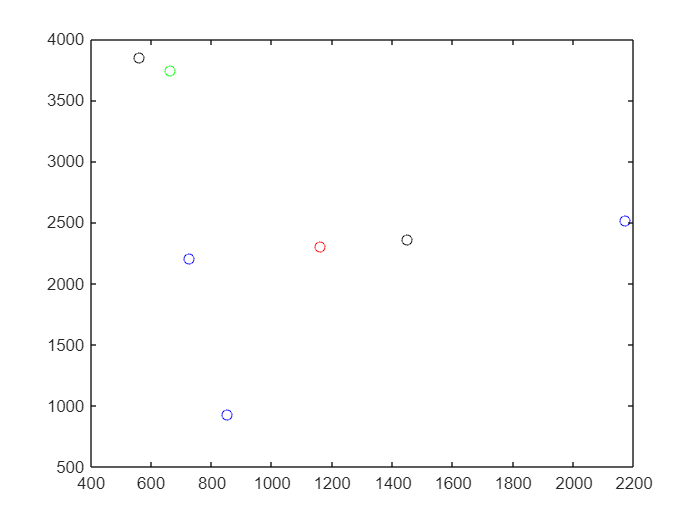


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

Model2.Airnode = [1624.69000000000	742.310000000000];
Model2.centrol = [1624.69000000000	742.310000000000];
Model2.Surnode = [854.060000000000	926.500000000000
                  2360.08000000000	915.360000000000
                  3095.47000000000	1088.36000000000];
Model2.CostAir = [800];
Model2.CostSur = [800; 1600; 800];
ub = [Model2.Airnode(1,1)+range,Model2.Airnode(1,2)+range];
lb = [Model2.Airnode(1,1)-range,Model2.Airnode(1,2)-range];

[Temp_T2, GBestFitness, Temp_L2] = PSOsolveTemp(Model2, Vel, ub, lb, iter_Max, N)

Temp_T2 = 1.0e+03 *

    1.6604    0.8423


GBestFitness = 1.0e+03 *

    1.1350    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348    1.1348


Temp_L2 = 1.0e+03 *

    2.3601    0.9154


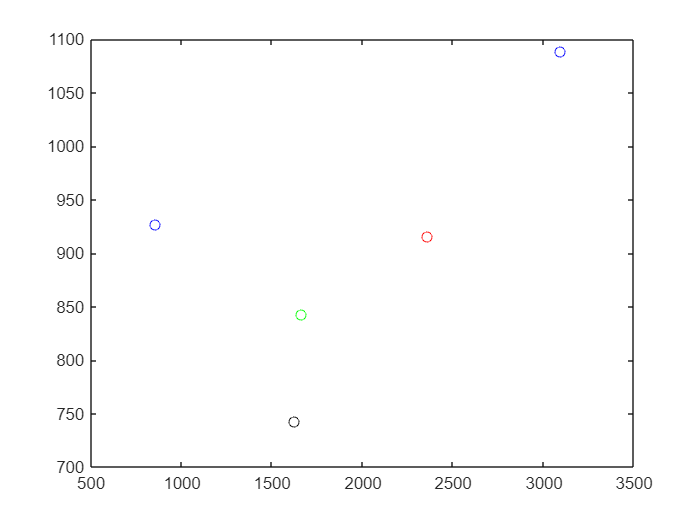


close
figure
plot(Model2.Surnode(:,1),Model2.Surnode(:,2),'bo');
hold on
plot(Model2.Airnode(:,1),Model2.Airnode(:,2),'ko');
plot(Temp_T2(1),Temp_T2(2),'go');
plot(Temp_L2(1),Temp_L2(2),'ro');

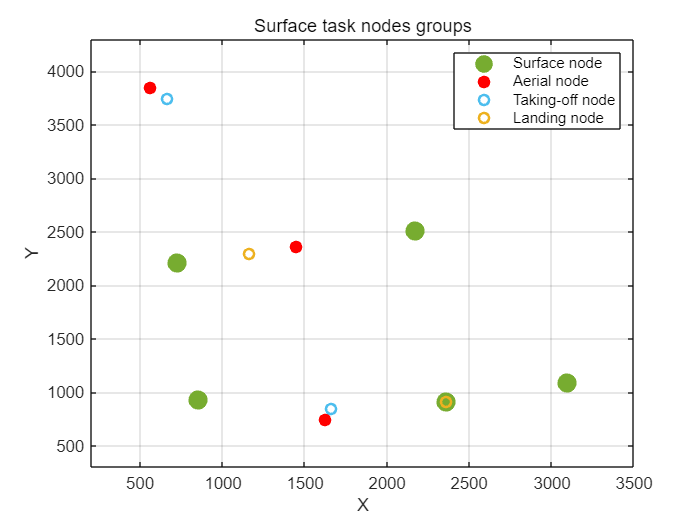

close
Surnode =  [Model1.Surnode
            Model2.Surnode];

Airnode = [Model1.Airnode
            Model2.Airnode];

Temp_T = [Temp_T1
    Temp_T2];

Temp_L = [Temp_L1
    Temp_L2];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([200 3500 300 4300])
title('Surface task nodes groups');
xlabel('X');
ylabel('Y');
grid on;

## 4号组

Model1.Airnode = [6774.42000000000	4419.72000000000
                5469.47000000000	4151.31000000000];
Model1.centrol = [6121.95000000000	4285.52000000000];
Model1.Surnode = [7776.28000000000	2763.69000000000
                5469.47000000000	4151.31000000000
                4827.53000000000	4017.42000000000];
Model1.CostAir = [800; 800];
Model1.CostSur = [800; 1600; 800];
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 = 1.0e+03 *

    6.6744    4.3197


GBestFitness = 1.0e+03 *

    1.8939    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895    1.8895


Temp_L1 = 1.0e+03 *

    5.4695    4.1513


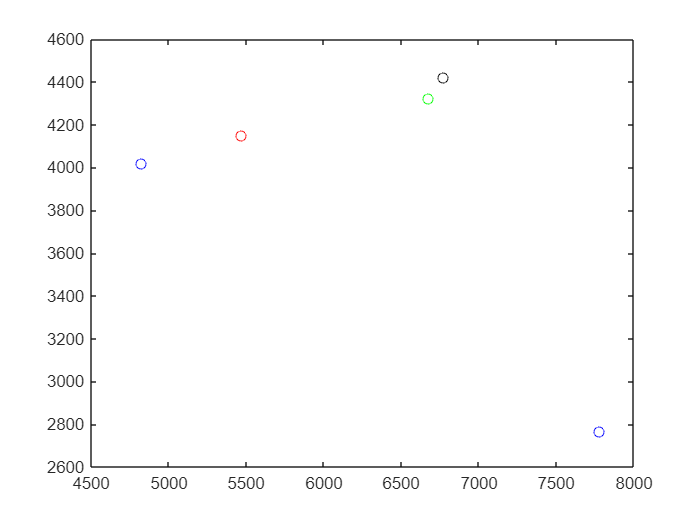


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

Model2.Airnode = [4936.75000000000	2145.67000000000
    6072.50000000000	2392.94000000000
    6640.42000000000	2516.56000000000];
Model2.centrol = [2780	3250];
Model2.Surnode = [4827.53000000000	4017.42000000000
                    4936.75000000000	2145.67000000000
                    6640.42000000000	2516.56000000000];
Model2.CostAir = [800;800;800];
Model2.CostSur = [800; 800; 800];
ub = [Model2.Airnode(1,1)+range,Model2.Airnode(1,2)+range];
lb = [Model2.Airnode(1,1)-range,Model2.Airnode(1,2)-range];

[Temp_T2, GBestFitness, Temp_L2] = PSOsolveTemp(Model2, Vel, ub, lb, iter_Max, N)

Temp_T2 = 1.0e+03 *

    4.9324    2.2196


GBestFitness = 1.0e+03 *

    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093    1.8093


Temp_L2 = 1.0e+03 *

    6.6404    2.5166


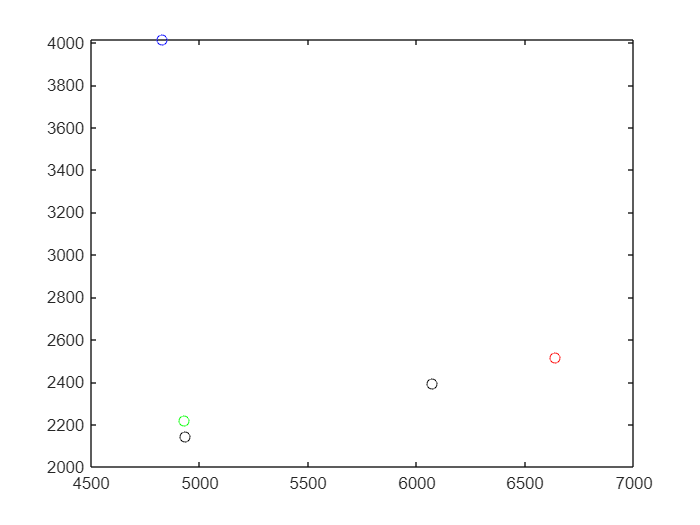


close
figure
plot(Model2.Surnode(:,1),Model2.Surnode(:,2),'bo');
hold on
plot(Model2.Airnode(:,1),Model2.Airnode(:,2),'ko');
plot(Temp_T2(1),Temp_T2(2),'go');
plot(Temp_L2(1),Temp_L2(2),'ro');

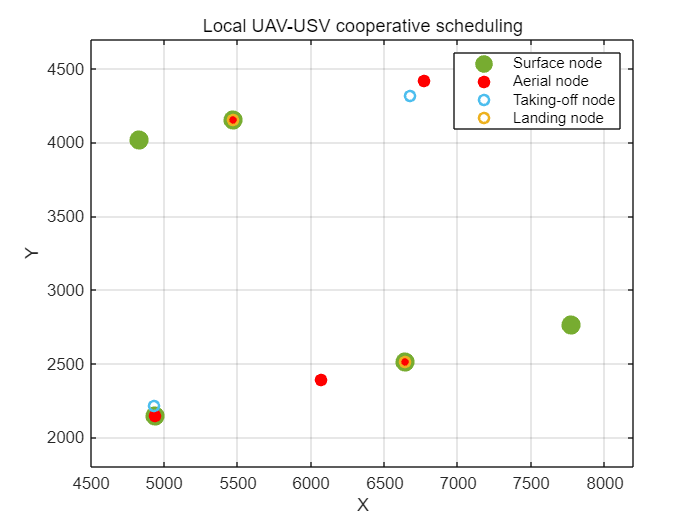

close
Surnode =  [Model1.Surnode
            Model2.Surnode];

Airnode = [Model1.Airnode
            Model2.Airnode];

Temp_T = [Temp_T1
    Temp_T2];

Temp_L = [Temp_L1
    Temp_L2];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([4500 8200 1800 4700])
title('Local UAV-USV cooperative scheduling');
xlabel('X');
ylabel('Y');
grid on;